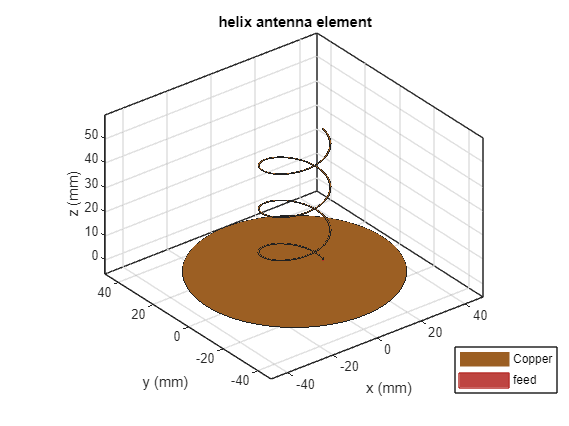

%% Antenna Properties 

TA = design(helix, 5000*1e6);
TA.Radius = 0.01255;
TA.Spacing = 0.017808;
TA.GroundPlaneRadius = 0.04;
TA.Substrate.Thickness = 0.054933;
TA.Conductor.Name = 'Copper';
TA.Conductor.Conductivity = 5.96*1e7;
TA.Conductor.Thickness = 3.556e-05;
% Show
show(TA) 

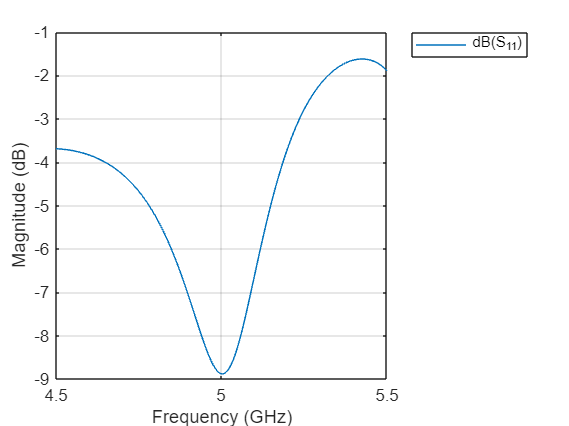


%% Antenna Analysis 
% Define plot frequency 
plotFrequency = 5*1e9;
% Define frequency range 
freqRange = (4500:5:5500)*1e6;
% Reference Impedance 
refImpedance = 50;
% sparameter
s = sparameters(TA, freqRange, refImpedance); 
rfplot(s)% pattern

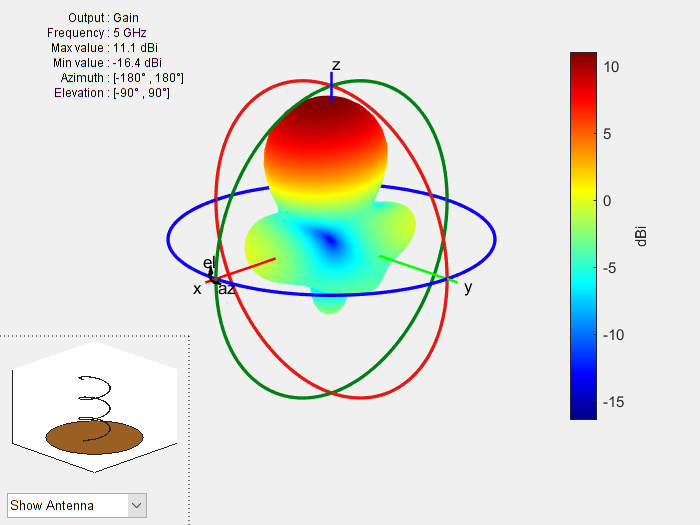

pattern(TA, plotFrequency)% azimuth

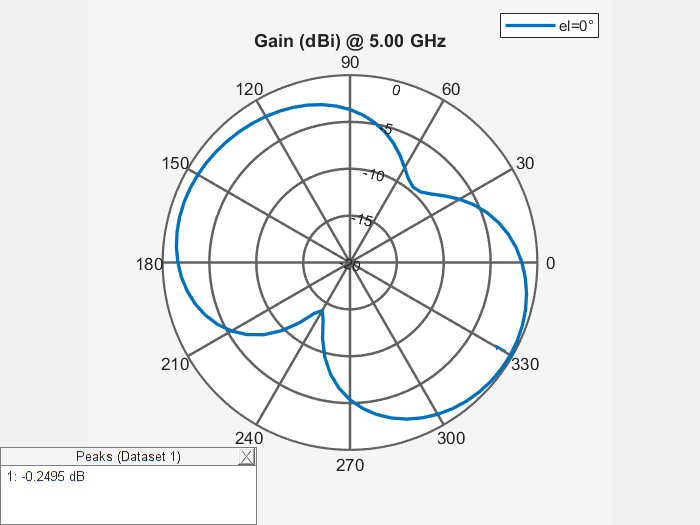

patternAzimuth(TA, plotFrequency, 0, 'Azimuth', 0:5:360)% elevation

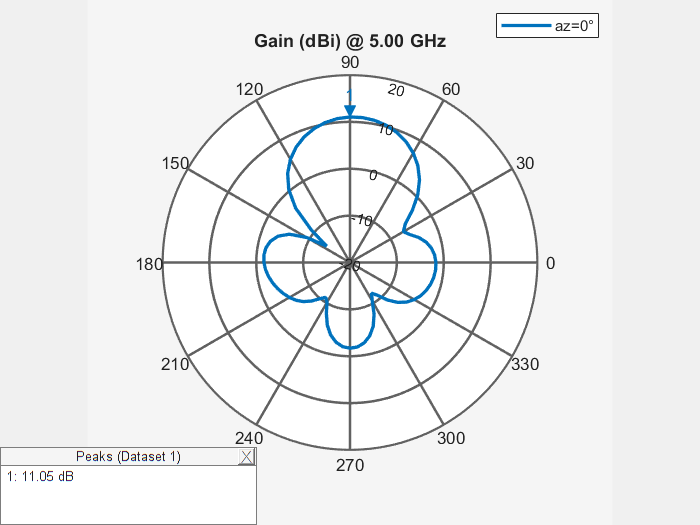

patternElevation(TA, plotFrequency,0,'Elevation',0:5:360)% current

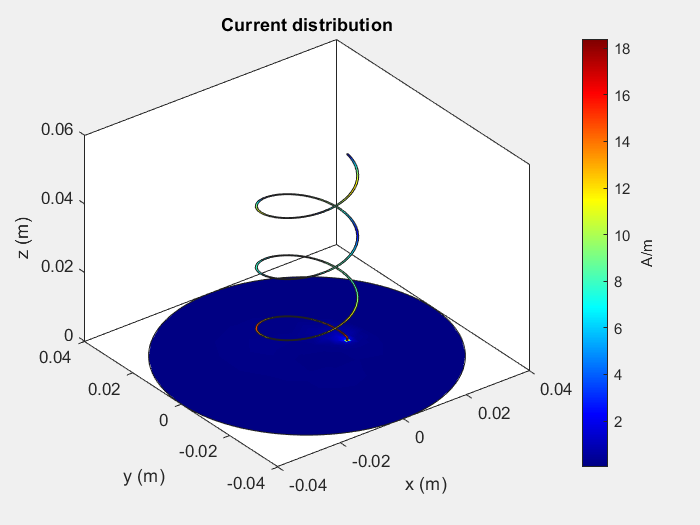

current(TA, plotFrequency)